Noise level: 0.1%, Optimal sampling: 25.0% of cycle (error: 0.093636)
Noise level: 1.0%, Optimal sampling: 26.0% of cycle (error: 0.914637)
Noise level: 2.0%, Optimal sampling: 74.0% of cycle (error: 1.822213)
Noise level: 5.0%, Optimal sampling: 75.0% of cycle (error: 4.571221)
Noise level: 10.0%, Optimal sampling: 75.0% of cycle (error: 9.342020)


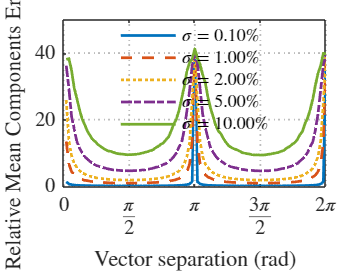

% Generate three-phase signal
fs = 10000;                       % Sampling frequency (Hz)
f = 50;                          % Signal frequency (Hz)
t = 0:1/fs:0.1-1/fs;             % Time vector (0.1 seconds)
N = length(t);                   % Number of samples

% Amplitude and phase for each phase
A = [1, 1, 1];                   % Equal amplitudes
phi = [0, -2*pi/3, 2*pi/3];      % 120° phase shift

% Generate three-phase signal
v = zeros(3, N);
for i = 1:3
    v(i,:) = A(i) * sin(2*pi*f*t + phi(i));
end

% Create reference bivector (for example, the ideal balanced case)
reference_bivector = ga3.Multivector(2,[1 -1 1]'/sqrt(3));

% Analyze bivectors with different noise levels
analyzeBivectorErrorWithNoise(v, t, f, reference_bivector);

% Calcular SNR aproximado equivalente para referencia
signal_power = mean(sum(v_base.^2, 1));
snr_equivalent = zeros(size(noise_std_levels));
for i = 1:length(noise_std_levels)
    noise_power = noise_std_levels(i)^2;
    snr_equivalent(i) = 10*log10(signal_power/noise_power);
end

% Mostrar equivalencia entre desviación estándar y SNR
fprintf('Niveles de ruido y sus SNR equivalentes aproximados:\n');
for i = 1:length(noise_std_levels)
    fprintf('  Desviación estándar: %.3f  →  SNR: %.1f dB\n', noise_std_levels(i), snr_equivalent(i));
end


% Código para analizar señales trifásicas y representar bivectores
% Utilizando bibliotecas de Álgebra Geométrica (GA3)

%% Inicialización y generación de señal trifásica
clear all; close all;

% Parámetros de la señal
fs = 10000;                       % Frecuencia de muestreo (Hz)
f = 50;                          % Frecuencia de la señal (Hz)
t = 0:1/fs:0.3-1/fs;             % Vector de tiempo (0.1 segundos)
N = length(t);                   % Número de muestras

% Amplitud y fase nominal para cada fase
A = [1, 1, 1];                   % Amplitudes iguales (pu)
phi = [0, -2*pi/3, 2*pi/3];      % Desfase entre fases (120°)

% Generar señales trifásicas
v = zeros(3, N);
for i = 1:3
    v(i,:) = A(i) * sin(2*pi*f*t + phi(i));
end

% Añadir perturbación en un punto específico (sag en una fase)
perturbation_start = round(N*0.6);
perturbation_end = round(N*0.8);
v(1, perturbation_start:perturbation_end) = v(1, perturbation_start:perturbation_end) * 0.7;  % 30% sag en fase A

% Calcular SNR aproximado equivalente para referencia
noise_std_levels = [0.001,0.01,0.02,0.05];
signal_power = mean(sum(v.^2, 1));
snr_equivalent = zeros(size(noise_std_levels));
for i = 1:length(noise_std_levels)
    noise_power = noise_std_levels(i)^2;
    snr_equivalent(i) = 10*log10(signal_power/noise_power);
end

data = load("fault_data\fault_A_B_G.mat");
v = [data.va;data.vb;data.vc];
t = data.t;
N = length(t);  


% % Mostrar equivalencia entre desviación estándar y SNR
% fprintf('Niveles de ruido y sus SNR equivalentes aproximados:\n');
% for i = 1:length(noise_std_levels)
%     fprintf('  Desviación estándar: %.3f  →  SNR: %.1f dB\n', noise_std_levels(i), snr_equivalent(i));
% end


%v = add_noise_to_3phase(v,0.001,"std");
%% Análisis de bivectores con diferentes separaciones temporales
% Vamos a probar con diferentes separaciones temporales
dt_samples = [1, 5, 10, 20, 40];  % Diferentes separaciones en muestras

figure;
subplot(2,1,1);
plot(t, v);
title('Señales trifásicas con perturbación');
xlabel('Tiempo (s)');
ylabel('Amplitud (pu)');
legend('Fase A', 'Fase B', 'Fase C');
grid on;

subplot(2,1,2);
hold on;
colors = {'r', 'g', 'b', 'm','k'};
legend_labels = cell(length(dt_samples), 1);

% Para cada separación temporal, calcular los bivectores
for dt_idx = 1:length(dt_samples)
    dt = dt_samples(dt_idx);
    
    % Calcular bivectores para cada punto del tiempo (excepto los últimos dt)
    bivector_norms = zeros(1, N-dt);
    bivector_angles = zeros(1, N-dt);
    bv_components = zeros(3, N-dt);
    
    for i = 1:(N-dt)
        % Crear vectores en GA3 para dos puntos temporales
        v1 = ga3.EncodeVector([v(1,i), v(2,i), v(3,i)]);
        v2 = ga3.EncodeVector([v(1,i+dt), v(2,i+dt), v(3,i+dt)]);
        
        % Calcular el bivector (producto exterior)
        bv = v1.op(v2);
        
        % Normalizar el bivector
        bv_norm = bv.norm();
        if bv_norm > 1e-6  % Evitar divisiones por cero
            bv_normalized = bv / bv_norm;
        else
            bv_normalized = bv;
        end
        
        % Extraer componentes del bivector normalizado
        bv_components(:,i) = bv_normalized.getDataArray();
        
        % Guardar norma del bivector original (área del paralelogramo)
        bivector_norms(i) = bv_norm;
        
        % Calcular ángulo respecto a una referencia (por ejemplo, primer bivector)
        if i == 1
            %reference_bv = bv_normalized;
            reference_bv = ga3.Multivector(2,[1 -1 1]'/sqrt(3));
            bivector_angles(i) = 0;
        else
            % El producto escalar de bivectores normalizados da el coseno del ángulo
            cos_angle = -reference_bv.sp(bv_normalized);
            bivector_angles(i) = acos(min(abs(cos_angle), 1)) * 180/pi;
        end
    end
    
    % Representar el ángulo del bivector respecto a la referencia inicial
    plot(t(1:N-dt), bivector_angles, colors{dt_idx}, 'LineWidth', 1.5);
    legend_labels{dt_idx} = sprintf('dt = %d muestras (%.1f ms)', dt, dt*1000/fs);
end

title('Ángulo del bivector normalizado respecto a la referencia inicial');
xlabel('Tiempo (s)');
ylabel('Ángulo (grados)');
legend(legend_labels);
grid on;

%% Visualización 3D del vector de tensión y el bivector
figure;

% Elegir un tiempo específico para visualizar (antes de la perturbación)
time_idx_normal = round(N*0.4);
% Elegir un tiempo durante la perturbación
time_idx_perturb = round(N*0.7);

% Visualizar para el caso normal
subplot(1,2,1);
visualize_3phase_bivector(v, t, time_idx_normal, dt_samples(2), fs);
title('Señal normal y su bivector');

% Visualizar para el caso con perturbación
subplot(1,2,2);
visualize_3phase_bivector(v, t, time_idx_perturb, dt_samples(2), fs);
title('Señal perturbada y su bivector');


figure;
plot(t(1:N-dt),(1/sqrt(3))*ones(1,length(1:N-dt)),t(1:N-dt),bv_components(1,:),t(1:N-dt),-bv_components(2,:),t(1:N-dt),bv_components(3,:));
title('Componentes del bivector');
xlabel('Tiempo (s)');
ylabel('Valor componentes');
legend_labels2 = {"reference","\sigma_{12}","\sigma_{23}","\sigma_{31}"};
legend(legend_labels2);
grid on;

%% Función para visualizar el vector 3D y su bivector
function visualize_3phase_bivector(v, t, time_idx, dt, fs)
    % Crear vectores en diferentes tiempos
    v1 = ga3.EncodeVector([v(1,time_idx), v(2,time_idx), v(3,time_idx)]);
    v2 = ga3.EncodeVector([v(1,time_idx+dt), v(2,time_idx+dt), v(3,time_idx+dt)]);
    
    % Calcular bivector
    bv = v1.op(v2);
    bv_norm = bv.norm();
    bv_normalized = bv * (1/bv_norm);
    
    % Obtener dual del bivector (normal al plano)
    normal_vector = bv_normalized.dual();
    normal_data = normal_vector.getDataArray();
    normal = [normal_data(1), normal_data(2), normal_data(3)];
    normal = -normal / norm(normal);
    
    % Visualizar vectores de tensión para 1 ciclo completo
    cycle_samples = round(fs/50);  % Muestras en un ciclo (para 50 Hz)
    start_idx = max(1, time_idx - cycle_samples/2);
    end_idx = min(length(t), start_idx + cycle_samples);
    
    % Dibujar trayectoria del vector
    plot3(v(1,start_idx:end_idx), v(2,start_idx:end_idx), v(3,start_idx:end_idx), 'b-', 'LineWidth', 1.5);
    hold on;
    
    % Dibujar vectores actuales
    v1_data = [v(1,time_idx), v(2,time_idx), v(3,time_idx)];
    v2_data = [v(1,time_idx+dt), v(2,time_idx+dt), v(3,time_idx+dt)];
    
    quiver3(0, 0, 0, v1_data(1), v1_data(2), v1_data(3), 0, 'r', 'LineWidth', 2);
    quiver3(0, 0, 0, v2_data(1), v2_data(2), v2_data(3), 0, 'g', 'LineWidth', 2);
    
    % Dibujar normal al plano (dual del bivector)
    scale_factor = max(max(abs(v(:))));
    quiver3(0, 0, 0, normal(1)*scale_factor, normal(2)*scale_factor, normal(3)*scale_factor, 0, 'm', 'LineWidth', 2);
    
    % Crear disco representando el plano del bivector
    [X, Y, Z] = create_oriented_disk(normal, scale_factor);
    surf(X, Y, Z, 'FaceColor', [0 0.7 0.7], 'FaceAlpha', 0.3, 'EdgeColor', 'none');
    
    % Configurar gráfica
    xlabel('Fase A (\sigma_1)');
    ylabel('Fase B (\sigma_2)');
    zlabel('Fase C (\sigma_3)');
    grid on;
    axis equal;
    view(45, 30);
    
    % Añadir leyenda
    legend('Trayectoria', 'Vector v(t)', 'Vector v(t+dt)', 'Normal (dual del bivector)', 'Plano del bivector');
end

%% Función auxiliar para crear un disco orientado
function [X, Y, Z] = create_oriented_disk(normal, radius)
    % Crear un disco orientado según el vector normal
    % Generar dos vectores perpendiculares al normal
    [v1, v2] = perpVectors(normal);
    
    % Crear un círculo en el plano
    theta = linspace(0, 2*pi, 50);
    X = zeros(2, 50);
    Y = zeros(2, 50);
    Z = zeros(2, 50);
    
    % Círculo exterior
    for i = 1:length(theta)
        point = radius * (v1 * cos(theta(i)) + v2 * sin(theta(i)));
        X(1, i) = point(1);
        Y(1, i) = point(2);
        Z(1, i) = point(3);
    end
    
    % Círculo interior para crear superficie
    for i = 1:length(theta)
        point = 0.1 * radius * (v1 * cos(theta(i)) + v2 * sin(theta(i)));
        X(2, i) = point(1);
        Y(2, i) = point(2);
        Z(2, i) = point(3);
    end
end

%% Función para calcular vectores perpendiculares
function [v1, v2] = perpVectors(n)
    % Generar dos vectores perpendiculares a n
    if abs(n(3)) < 0.9
        % Si n no está cerca del eje z, usamos el producto vectorial con [0,0,1]
        v1 = cross([0, 0, 1], n);
    else
        % Si n está cerca del eje z, usamos el producto vectorial con [0,1,0]
        v1 = cross([0, 1, 0], n);
    end
    
    v1 = v1 / norm(v1);  % Normalizar
    v2 = cross(n, v1);   % Obtener el tercer vector perpendicular a n y v1
    v2 = v2 / norm(v2);  % Normalizar
end

%% Función para añadir ruido a una señal con una desviación estándar determinada
function noisy_signal = add_noise_with_std(signal, noise_std)
    % Generar ruido gaussiano con la desviación estándar especificada
    noise = noise_std * randn(size(signal));
    
    % Añadir ruido a la señal
    noisy_signal = signal + noise;
end

# **Analizar señal Real**

% Cargar Señal
data = load("fault_data\caseR004_a(1).mat");
%current = [-data.ia;-data.ib;-data.ic];
voltage = [R004V_R23(1,:);R004V_R23(2,:);R004V_R23(3,:)];
f = 50; % Frecuancia del sistema
fs = 100000;
%t = (0:length(voltage(1,:))-1)/fs;
t = R004_t;
N = length(t); % Número de muestras
percent = 25; % Separación de vectores en porcentaje de ciclo 

% [p_i,PAt,P,~,~,~] = calcular_potencia_trifasica(voltage,current);
% p_inst_0 = p_i - P;


s = voltage;

% Ejemplo de filtro de media móvil
parametros.ventana = 25; % Tamaño de la ventana
s = filtrar_ruido(s, fs, 'media_movil', parametros);


cycle_period = 1/f;
samples_per_cycle = round(cycle_period / (t(2) - t(1)));
dt = round(samples_per_cycle * percent / 100);

bivector_angles = zeros(1, N-dt);
bv_components = zeros(3, N-dt);
reference_bv = ga3.Multivector(2,[1 -1 1]'/sqrt(3));

for i = 1:(N - dt)
    % Create geometric vectors for the voltage samples
    bv = calcularBivectorNormalizado([s(1,i), s(2,i), s(3,i)],[s(1,i+dt), s(2,i+dt), s(3,i+dt)]);
    
    % Extract bivector components
    bv_components(:,i) = abs(bv.getDataArray());

    if i == 1
        bivector_angles(i) = 0;
    else
        % El producto escalar de bivectores normalizados da el coseno del ángulo
        cos_angle = -reference_bv.sp(bv);
        bivector_angles(i) = acos(min(abs(cos_angle), 1)) * 180/pi;
    end    
end


figure;
plot(t, s(1,:),t,s(2,:),t,s(3,:));
title('Señales trifásicas con perturbación');
xlabel('Tiempo (s)');
ylabel('Amplitud (u)');
legend('Fase A', 'Fase B', 'Fase C');
grid on;

bivector_angles2 = movmean(bivector_angles, 500);
figure;
plot(t(1:N-dt), bivector_angles2, 'LineWidth', 1.5);
title('Ángulo del bivector normalizado respecto a la referencia inicial');
xlabel('Tiempo (s)');
ylabel('Ángulo (grados)');
grid on;

bv_components2 = movmedian(bv_components, 1);

figure;
plot(t(1:N-dt),(1/sqrt(3))*ones(1,length(1:N-dt)),t(1:N-dt),bv_components2(1,:),t(1:N-dt),bv_components2(2,:),t(1:N-dt),bv_components2(3,:));
title('Componentes del bivector');
xlabel('Tiempo (s)');
ylabel('Valor componentes');
legend_labels2 = {"reference","\sigma_{12}","\sigma_{23}","\sigma_{31}"};
legend(legend_labels2);
grid on;

% Elegir un tiempo específico para visualizar (antes de la perturbación)
time_idx_normal = round(N*0.2);
% Elegir un tiempo durante la perturbación
time_idx_perturb = round(N*0.492683);

figure;
% Visualizar para el caso normal
subplot(1,2,1);
visualize_3phase_bivector(s, t, time_idx_normal, dt, fs);
title('Señal normal y su bivector');

% Visualizar para el caso con perturbación
subplot(1,2,2);
visualize_3phase_bivector(s, t, time_idx_perturb, dt, fs);
title('Señal perturbada y su bivector');

Bivector Components por Falla

function analyzeFaultBivectors(fault_files_pattern, ref_value, cycle_percent)
    % ANALYZEFAULTBIVECTORS Analyzes bivector components for different fault types
    %
    % Inputs:
    %   fault_files_pattern - String pattern for fault .mat files (e.g., 'fault_*.mat')
    %   ref_value - Reference value for bivector components (default: 1/sqrt(3))
    %   cycle_percent - Percentage of cycle to use for bivector calculation (default: 25)
    
    % Default values
    if nargin < 2
        ref_value = 1/sqrt(3);
    end
    if nargin < 3
        cycle_percent = 25; % Use 25% of cycle by default
    end
    
    % Find all fault files
    fault_files = dir(fault_files_pattern);
    
    if isempty(fault_files)
        error('No fault files found matching the pattern: %s', fault_files_pattern);
    end
    
    % Initialize result arrays
    num_files = length(fault_files);
    fault_names = cell(num_files, 1);
    bivector_components = zeros(num_files, 3);
    component_deviations = zeros(num_files, 3);
    total_deviation = zeros(num_files, 1);
    
    % Process each fault file
    for i = 1:num_files
        % Load fault data
        file_path = fullfile(fault_files(i).folder, fault_files(i).name);
        fault_data = load(file_path);
        
        % Extract fault name from file data or filename
        if isfield(fault_data, 'faultType')
            fault_names{i} = fault_data.faultType;
        else
            [~, fault_name, ~] = fileparts(fault_files(i).name);
            fault_names{i} = fault_name;
        end
        
        % Extract time data
        if isfield(fault_data, 't')
            time = fault_data.t;
        else
            error('Could not find time data (t) in file: %s', fault_files(i).name);
        end
        
        % Extract and combine voltage data into 3xN matrix
        if isfield(fault_data, 'va') && isfield(fault_data, 'vb') && isfield(fault_data, 'vc')
            va = fault_data.va;
            vb = fault_data.vb;
            vc = fault_data.vc;
            
            % Make sure they're all column vectors
            if size(va, 1) == 1
                va = va';
                vb = vb';
                vc = vc';
            end
            
            % Combine into 3xN voltage matrix
            voltage = [va, vb, vc]';
        else
            error('Could not find voltage data (va, vb, vc) in file: %s', fault_files(i).name);
        end
        
        % Assume fault is in the middle third of the signal
        fault_start = round(length(time) / 3);
        fault_end = round(2 * length(time) / 3);
        
        % Estimate frequency from time vector
        time_diff = time(2) - time(1);
        total_time = time(end) - time(1);
        num_cycles = total_time * 50; % Assuming 50Hz system
        
        % Calculate samples per cycle
        samples_per_cycle = length(time) / num_cycles;
        freq = 50; % Assume 50Hz for power system
        
        % Calculate bivector components during fault
        components = calculateBivectorComponents(voltage, time, freq, cycle_percent, fault_start, fault_end);
        
        % Store results
        bivector_components(i, :) = components;
        component_deviations(i, :) = abs(components - ref_value);
        total_deviation(i) = sqrt(sum((components - ref_value).^2));
        
        fprintf('Processed: %s\n', fault_names{i});
    end
    
    % Display results in table format
    createResultTable(fault_names, bivector_components, component_deviations, total_deviation, ref_value);
    
    % Also create a visual comparison
    plotBivectorComponents(fault_names, bivector_components, ref_value);
end

function components = calculateBivectorComponents(voltage, time, freq, cycle_percent, fault_start, fault_end)
    % Calculate bivector components during fault
    
    % Calculate sample distance based on cycle percentage
    cycle_period = 1/freq;
    time_step = time(2) - time(1);
    samples_per_cycle = round(cycle_period / time_step);
    sample_distance = round(samples_per_cycle * cycle_percent / 100);
    
    % Initialize storage for bivector components
    components_sum = [0, 0, 0];
    count = 0;
    
    % Calculate bivectors for samples during fault
    for i = fault_start:(fault_end - sample_distance)
        % Create vectors for two points
        v1 = ga3.EncodeVector([voltage(1,i), voltage(2,i), voltage(3,i)]);
        v2 = ga3.EncodeVector([voltage(1,i+sample_distance), voltage(2,i+sample_distance), voltage(3,i+sample_distance)]);
        
        % Calculate bivector
        bv = v1.op(v2);
        
        % Normalize bivector
        bv_norm = bv.norm();
        if bv_norm > 1e-6
            bv_normalized = bv * (1/bv_norm);
            
            % Extract components (assuming σ12, σ23, σ31 are at indices 5,6,7)
            comp = bv_normalized.getDataArray();
            
            % Add to sum (taking absolute values as orientation doesn't matter)
            components_sum = components_sum + abs([comp(1), comp(3), -comp(2)]);
            count = count + 1;
        end
    end
    
    % Calculate average components
    if count > 0
        components = components_sum / count;
    else
        components = [NaN, NaN, NaN];
        warning('No valid bivectors calculated during fault');
    end
end

function createResultTable(fault_names, bivector_components, component_deviations, total_deviation, ref_value)
    % Create and display results in a table format
    
      
    % Create table
    results_table = table();
    results_table.FaultType = fault_names;
    results_table.Sigma12 = bivector_components(:, 1);
    results_table.Sigma23 = bivector_components(:, 2);
    results_table.Sigma31 = bivector_components(:, 3);
    results_table.Dev_Sigma12 = component_deviations(:, 1);
    results_table.Dev_Sigma23 = component_deviations(:, 2);
    results_table.Dev_Sigma31 = component_deviations(:, 3);
    results_table.TotalDeviation = total_deviation;
    
    % Sort table by total deviation
    results_table = sortrows(results_table, 'TotalDeviation', 'descend');
    
    % Display table
    fprintf('\n--- Bivector Components Analysis Results ---\n');
    fprintf('Reference value: %.6f\n\n', ref_value);
    disp(results_table);
    
    % Save table to CSV file
    writetable(results_table, 'fault_bivector_analysis.csv');
    fprintf('Results saved to fault_bivector_analysis.csv\n');
    
    % Create LaTeX table
    createLatexTable(results_table, ref_value);
end

function [reordered_table, ordered_indices] = orderByFaultType(results_table, fault_order)
    % Reorder table according to specific fault type order
    
    % Initialize array for ordered indices
    num_rows = height(results_table);
    ordered_indices = zeros(num_rows, 1);
    missing_indices = [];
    next_pos = 1;
    
    % Match fault types according to the order
    for i = 1:length(fault_order)
        desired_type = fault_order{i};
        
        % Find all rows that match or contain this fault type
        for j = 1:num_rows
            % Skip already ordered rows
            if any(ordered_indices == j)
                continue;
            end
            
            % Check for exact match or pattern match
            current_type = results_table.FaultType{j};
            if strcmpi(current_type, desired_type) || ...
               contains(current_type, desired_type, 'IgnoreCase', true)
                ordered_indices(next_pos) = j;
                next_pos = next_pos + 1;
                break;
            end
        end
    end
    
    % Add any remaining fault types not in the specified order
    for j = 1:num_rows
        if ~any(ordered_indices == j)
            missing_indices = [missing_indices, j];
        end
    end
    
    % Add missing indices at the end
    for i = 1:length(missing_indices)
        ordered_indices(next_pos) = missing_indices(i);
        next_pos = next_pos + 1;
    end
    
    % Remove zeros if not all types were found
    ordered_indices = ordered_indices(ordered_indices > 0);
    
    % Create reordered table
    reordered_table = results_table(ordered_indices, :);
    
    % Print warning if some specified fault types weren't found
    found_types = 0;
    for i = 1:length(fault_order)
        type_found = false;
        for j = 1:height(reordered_table)
            if strcmpi(reordered_table.FaultType{j}, fault_order{i}) || ...
               contains(reordered_table.FaultType{j}, fault_order{i}, 'IgnoreCase', true)
                type_found = true;
                break;
            end
        end
        
        if type_found
            found_types = found_types + 1;
        else
            fprintf('Warning: Fault type "%s" not found in the data.\n', fault_order{i});
        end
    end
    
    fprintf('Found %d out of %d specified fault types.\n', found_types, length(fault_order));
end


function createLatexTable(results_table, ref_value)
    % Create a LaTeX formatted table
    
    filename = 'fault_bivector_analysis.tex';
    fid = fopen(filename, 'w');
    
    % Table header
    fprintf(fid, '\\begin{table}[htbp]\n');
    fprintf(fid, '\\centering\n');
    fprintf(fid, '\\caption{Bivector Components for Different Fault Types (Reference: $%.4f$)}\n', ref_value);
    fprintf(fid, '\\label{tab:fault_bivectors}\n');
    fprintf(fid, '\\begin{tabular}{|l|c|c|c|c|}\n');
    fprintf(fid, '\\hline\n');
    fprintf(fid, 'Fault Type & $\\sigma_{12}$ & $\\sigma_{23}$ & $\\sigma_{31}$ & Total Deviation \\\\\n');
    fprintf(fid, '\\hline\n');
    
    % Table data
    for i = 1:height(results_table)
        fprintf(fid, '%s & %.4f & %.4f & %.4f & %.4f \\\\\n', ...
            results_table.FaultType{i}, ...
            results_table.Sigma12(i), ...
            results_table.Sigma23(i), ...
            results_table.Sigma31(i), ...
            results_table.TotalDeviation(i));
    end
    
    % Table footer
    fprintf(fid, '\\hline\n');
    fprintf(fid, '\\end{tabular}\n');
    fprintf(fid, '\\end{table}\n');
    
    fclose(fid);
    fprintf('LaTeX table saved to %s\n', filename);
end

function plotBivectorComponents(fault_names, bivector_components, ref_value)
    
    % Define the desired order of fault types
    desired_order = {'A-G', 'B-G', 'C-G', 'A-B-G', 'B-C-G', 'C-A-G', 'A-B', 'B-C', 'C-A', 'A-B-C'};
    
    [ordered_names, ordered_components] = orderFaultsByDesiredSequence(fault_names, bivector_components, desired_order);
    
    figure('Position', [100, 100, 800, 400], 'Color', 'w');
    
    % Create bar chart of components
    bar(ordered_components);
    hold on;
    
    % Add reference line
    plot([0, length(ordered_names)+0.1], [ref_value, ref_value], 'r--', 'LineWidth', 1.5);
    
    % Customize plot
    grid on;
    %title('Bivector Components by Fault Type', 'Interpreter', 'latex', 'FontSize', 14);
    ylabel('Component Value', 'Interpreter', 'latex', 'FontSize', 12);
    legend({'$\sigma_{12}$', '$\sigma_{23}$', '$\sigma_{31}$', 'Reference'}, ...
           'Interpreter', 'latex', 'Location', 'best');
    set(gca, 'XTick', 1:length(ordered_names), 'XTickLabel', ordered_names, ...
        'XTickLabelRotation', 45, 'TickLabelInterpreter', 'none');
    
    % Create radar chart
    figure;
    num_faults = length(ordered_names);
    
    % Create data for radar chart (normalize to reference)
    radar_data = ordered_components ./ ref_value;
    
    % Plot reference circle
    theta = linspace(0, 2*pi, 100);
    x_circle = cos(theta);
    y_circle = sin(theta);
    plot(x_circle, y_circle, 'k--', 'LineWidth', 1);
    hold on;
    
    % Plot each fault as a triangle in the radar plot
    colors = jet(num_faults);
    legend_entries = cell(num_faults, 1);
    
    for i = 1:num_faults
        % Create triangle coordinates
        r_values = radar_data(i, :);
        theta_values = [0, 2*pi/3, 4*pi/3];
        x = r_values .* cos(theta_values);
        y = r_values .* sin(theta_values);
        
        % Close the triangle
        x = [x, x(1)];
        y = [y, y(1)];
        
        % Plot
        plot(x, y, '-', 'Color', colors(i,:), 'LineWidth', 2);
        patch(x, y, colors(i,:), 'FaceAlpha', 0.2);
        
        legend_entries{i} = fault_names{i};
    end
    
    % Add axes labels
    text(1.1, 0, '$\sigma_{12}$', 'Interpreter', 'latex', 'FontSize', 12, 'HorizontalAlignment', 'left');
    text(-0.55, 0.95, '$\sigma_{23}$', 'Interpreter', 'latex', 'FontSize', 12);
    text(-0.55, -0.95, '$\sigma_{31}$', 'Interpreter', 'latex', 'FontSize', 12);
    
    % Configure plot
    axis equal;
    axis off;
    title('Normalized Bivector Components Radar Plot', 'Interpreter', 'latex', 'FontSize', 14);
    legend(legend_entries, 'Location', 'eastoutside', 'Interpreter', 'none');
    
    % Save figure
    print('fault_bivector_components', '-dpdf', '-r300');
    fprintf('Component visualization saved to fault_bivector_components.pdf\n');
end

function [ordered_names, ordered_components] = orderFaultsByDesiredSequence(fault_names, bivector_components, desired_order)
    % A simpler approach to order fault data according to desired sequence
    % Returns ordered names and components, with names not in desired_order at the end
    
    n_faults = length(fault_names);
    ordered_names = cell(n_faults, 1);
    ordered_components = zeros(n_faults, size(bivector_components, 2));
    
    % Track which faults have been processed
    processed = false(n_faults, 1);
    next_position = 1;
    
    % First, place faults according to desired order
    for i = 1:length(desired_order)
        desired = desired_order{i};
        found = false;
        
        % Look for exact match
        for j = 1:n_faults
            if ~processed(j) && strcmpi(fault_names{j}, desired)
                ordered_names{next_position} = fault_names{j};
                ordered_components(next_position, :) = bivector_components(j, :);
                processed(j) = true;
                next_position = next_position + 1;
                found = true;
                break;
            end
        end
        
        % If no exact match, try partial match
        if ~found
            for j = 1:n_faults
                if ~processed(j) && (contains(lower(fault_names{j}), lower(desired)) || ...
                                   contains(lower(desired), lower(fault_names{j})))
                    ordered_names{next_position} = fault_names{j};
                    ordered_components(next_position, :) = bivector_components(j, :);
                    processed(j) = true;
                    next_position = next_position + 1;
                    found = true;
                    break;
                end
            end
        end
    end
    
    % Add any remaining unprocessed faults at the end
    for j = 1:n_faults
        if ~processed(j)
            ordered_names{next_position} = fault_names{j};
            ordered_components(next_position, :) = bivector_components(j, :);
            next_position = next_position + 1;
        end
    end
    
    % Print the ordering for debugging
    fprintf('Ordered fault types:\n');
    for i = 1:length(ordered_names)
        fprintf('%d. %s\n', i, ordered_names{i});
    end
end

% O especificar el valor de referencia y el porcentaje de ciclo
analyzeFaultBivectors("fault_data\fault_*.mat", 1/sqrt(3), 25);

# **Análisis de Ajuste de elipse con distintos niveles de ruido**

% Análisis simplificado de ajuste de elipses
% Este script analiza el error en la suma de semiejes para diferentes cantidades de puntos y niveles de ruido

% Configuración del estilo LaTeX para figuras
set(0, 'DefaultTextInterpreter', 'latex');
set(0, 'DefaultAxesTickLabelInterpreter', 'latex');
set(0, 'DefaultLegendInterpreter', 'latex');
set(0, 'DefaultAxesFontSize', 12);

% Parámetros de la elipse original
centroOriginal = [0, 0];        % Centro de la elipse
% semiejeMayorOriginal = 50;      % Semieje mayor
% semiejeMenorOriginal = 20;       % Semieje menor
% anguloOriginal = pi/4;          % Ángulo de inclinación (45 grados)
% sumaOriginal = semiejeMayorOriginal + semiejeMenorOriginal; % Suma de semiejes original
parametrosElipses = [
    50, 20, pi/4;    % Elipse original inclinada 45°
    80, 50, 0;        % Elipse alineada con los ejes
    120, 30, pi/6;    % Elipse más alargada, inclinada 30°
    70, 60, pi/3;     % Elipse casi circular, inclinada 60°
    150, 80, pi/2     % Elipse grande vertical
];
numElipses = size(parametrosElipses, 1);

% Configuración del experimento
numPuntosTotal = 200;           % Total de puntos en la elipse completa
incremento = 5;                 % Incremento en el número de puntos para cada prueba
numPuntosVector = 5:incremento:numPuntosTotal; % Vector con los tamaños de subconjuntos a probar
nivelesRuido = [0, 0.01, 0.02, 0.05, 0.1];  % Niveles de ruido como fracción del semieje mayor
numIteraciones = 200;            % Número de iteraciones para promediar resultados

% Preasignar matriz para almacenar errores en la suma de semiejes
errorSumaSemiejes = zeros(length(numPuntosVector), length(nivelesRuido), numIteraciones);
error1 = zeros(length(numPuntosVector), numElipses);

% Ciclo principal
for iteracion = 1:numIteraciones
    % Generar puntos en una elipse perfecta para esta iteración
    t = linspace(0, 2*pi, numPuntosTotal+1);
    t = t(1:end-1); % Eliminar el punto duplicado
    
    
    
    for j = 1:length(nivelesRuido)
        ruido = nivelesRuido(j);
        % Añadir ruido a todos los puntos
        rng(iteracion*100 + j); % Semilla para reproducibilidad, pero diferente para cada iteración y nivel

        for elipse = 1:numElipses

            semiejeMayorOriginal = parametrosElipses(elipse, 1);
            semiejeMenorOriginal = parametrosElipses(elipse, 2);
            anguloOriginal = parametrosElipses(elipse, 3);
            sumaOriginal = semiejeMayorOriginal + semiejeMenorOriginal;

            % Puntos de la elipse sin ruido
            X0 = centroOriginal(1) + semiejeMayorOriginal * cos(t) * cos(anguloOriginal) - semiejeMenorOriginal * sin(t) * sin(anguloOriginal);
            Y0 = centroOriginal(2) + semiejeMayorOriginal * cos(t) * sin(anguloOriginal) + semiejeMenorOriginal * sin(t) * cos(anguloOriginal);


            ruidoX = ruido * semiejeMayorOriginal * randn(size(X0));
            ruidoY = ruido * semiejeMayorOriginal * randn(size(Y0));
            
            X_ruido = X0 + ruidoX;
            Y_ruido = Y0 + ruidoY;
            
            % Para cada subconjunto de puntos, realizar el ajuste
            for i = 1:length(numPuntosVector)
                numPuntos = numPuntosVector(i);
                
                % Tomar los primeros numPuntos puntos
                if numIteraciones + numPuntos > numPuntosTotal
                    rest = numIteraciones + numPuntos - numPuntosTotal;
                    X = [X_ruido(numIteraciones-1:numPuntosTotal),X_ruido(1:rest)];
                    Y = [Y_ruido(numIteraciones-1:numPuntosTotal),Y_ruido(1:rest)];
    
                else
                    X = X_ruido(numIteraciones:numPuntos);
                    Y = Y_ruido(numIteraciones:numPuntos);
                end
                
                
                % Ajustar elipse usando tus funciones
                try
                    % Ajustar la elipse con los puntos ruidosos
                    Q = fitEllipse00GAC([X', Y']);
                    % cetro = [0,0];
                    % semiejes = [rM,rm];
    
                    % Extraer parámetros de la elipse ajustada
                    [~, semiejes, angulo] = extractEllipseParameters(Q);
    
                    % Calcular error relativo en la suma de semiejes
                    sumaSemiejes = semiejes(1) + semiejes(2);
                    error1(i,elipse) = (abs(sumaSemiejes - sumaOriginal) / sumaOriginal) + min(abs(angulo - anguloOriginal), abs(abs(angulo - anguloOriginal) - pi)) / (pi/2);
                    
                catch
                    % Si el ajuste falla, registrar un error (NaN)
                    error1(i,elipse) = NaN;
                end
            end
            errorSumaSemiejes(:, j, iteracion) = mean(error1, 2 ,"omitnan");
        end
    end
    fprintf('Iteración %d de %d completada\n', iteracion, numIteraciones);
end

Iteración 1 de 200 completada
Iteración 2 de 200 completada
Iteración 3 de 200 completada
Iteración 4 de 200 completada
Iteración 5 de 200 completada
Iteración 6 de 200 completada
Iteración 7 de 200 completada
Iteración 8 de 200 completada
Iteración 9 de 200 completada
Iteración 10 de 200 completada
Iteración 11 de 200 completada
Iteración 12 de 200 completada
Iteración 13 de 200 completada
Iteración 14 de 200 completada
Iteración 15 de 200 completada
Iteración 16 de 200 completada
Iteración 17 de 200 completada
Iteración 18 de 200 completada
Iteración 19 de 200 completada
Iteración 20 de 200 completada
Iteración 21 de 200 completada
Iteración 22 de 200 completada
Iteración 23 de 200 completada
Iteración 24 de 200 completada
Iteración 25 de 200 completada
Iteración 26 de 200 completada
Iteración 27 de 200 completada
Iteración 28 de 200 completada
Iteración 29 de 200 completada
Iteración 30 de 200 completada
Iteración 31 de 200 completada
Iteración 32 de 200 completada
Iteración 33 de 2

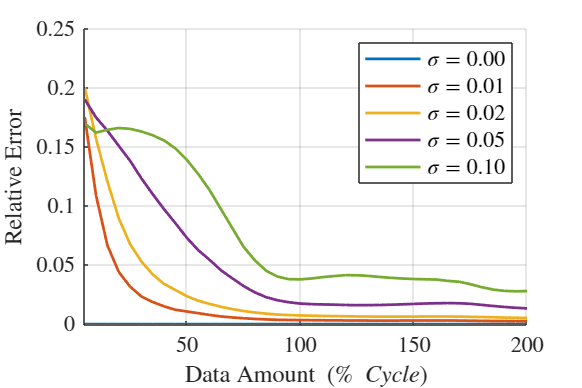


% Promediar errores a través de las iteraciones
errorSumaSemiejesProm = mean(errorSumaSemiejes, 3, 'omitnan');
stdSumaSemiejes = std(errorSumaSemiejes, 0, 3, 'omitnan');

% Visualizar resultados - Error en la suma de semiejes
figure('Position', [100, 100, 600, 400]);
hold on;
colores = lines(length(nivelesRuido));
leyendaTexto = cell(1, length(nivelesRuido));

for j = 1:length(nivelesRuido)
    plot(numPuntosVector, errorSumaSemiejesProm(:, j), 'Color', colores(j,:), 'LineWidth', 1.5);
    leyendaTexto{j} = sprintf('$\\sigma = %.2f$', nivelesRuido(j));
end

%title('$\textrm{Error relativo en la suma de semiejes} (|a+b - a_{0}-b_{0}|/(a_{0}+b_{0}))$', 'FontSize', 14);
xlabel('$\textrm{Data Amount}\ (\%\ Cycle)$', 'FontSize', 13);
ylabel('$\textrm{Relative Error}$', 'FontSize', 13);
legend(leyendaTexto, 'Location', 'northeast', 'FontSize', 12);
grid on;
%set(gca, 'XScale', 'log'); % Escala logarítmica para mejor visualización
xlim([min(numPuntosVector), max(numPuntosVector)]);
hold off;

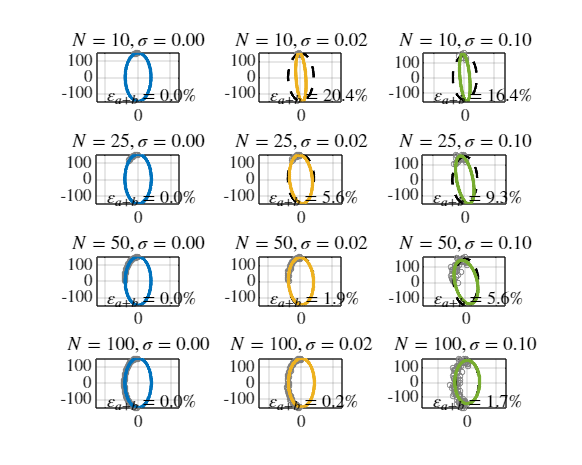


% Guardar la figura
%saveas(gcf, 'error_suma_semiejes.pdf');

% Visualizar algunos ejemplos de ajuste
figure('Position', [100, 100, 1000, 800]);
puntosSeleccionados = [10, 25, 50 ,100]; % Puntos a visualizar
ruidosSeleccionados = [1, 3, 5]; % Índices 1, 3, 5 de nivelesRuido

for idx = 1:length(puntosSeleccionados)
    numPuntos = puntosSeleccionados(idx);
    
    % Generar puntos en una elipse perfecta
    t = linspace(0, 2*pi, numPuntosTotal+1);
    t = t(1:end-1);
    
    % Puntos de la elipse sin ruido
    X0 = centroOriginal(1) + semiejeMayorOriginal * cos(t) * cos(anguloOriginal) - semiejeMenorOriginal * sin(t) * sin(anguloOriginal);
    Y0 = centroOriginal(2) + semiejeMayorOriginal * cos(t) * sin(anguloOriginal) + semiejeMenorOriginal * sin(t) * cos(anguloOriginal);
    
    for j_idx = 1:length(ruidosSeleccionados)
        j = ruidosSeleccionados(j_idx);
        ruido = nivelesRuido(j);
        
        subplot(length(puntosSeleccionados), length(ruidosSeleccionados), (idx-1)*length(ruidosSeleccionados) + j_idx);
        
        % Añadir ruido a los puntos (usar la misma semilla para reproducibilidad)
        rng(42);
        ruidoX = ruido * semiejeMayorOriginal * randn(size(X0));
        ruidoY = ruido * semiejeMayorOriginal * randn(size(Y0));
        
        X_ruido = X0 + ruidoX;
        Y_ruido = Y0 + ruidoY;
        
        % Tomar los primeros numPuntos puntos
        X = X_ruido(1:numPuntos);
        Y = Y_ruido(1:numPuntos);
        
        % Trazar elipse original para referencia
        t_fino = linspace(0, 2*pi, 500);
        X_original = centroOriginal(1) + semiejeMayorOriginal * cos(t_fino) * cos(anguloOriginal) - semiejeMenorOriginal * sin(t_fino) * sin(anguloOriginal);
        Y_original = centroOriginal(2) + semiejeMayorOriginal * cos(t_fino) * sin(anguloOriginal) + semiejeMenorOriginal * sin(t_fino) * cos(anguloOriginal);
        
        % Ajustar elipse
        try
            Q = fitEllipse00GAC([X', Y']);
            % cetro = [0,0];
            % semiejes = [rM,rm];
            
            [centro, semiejes, angulo] = extractEllipseParameters(Q);

            % d = fitellipse(X,Y);
            % semiejes = [d(3),d(4)];
            % centro = [d(1),d(2)];
            % angulo = d(5);

            % Generar puntos para la elipse ajustada
            X_ajustada = centro(1) + semiejes(1) * cos(t_fino) * cos(angulo) - semiejes(2) * sin(t_fino) * sin(angulo);
            Y_ajustada = centro(2) + semiejes(1) * cos(t_fino) * sin(angulo) + semiejes(2) * sin(t_fino) * cos(angulo);
            
            % Graficar
            plot(X, Y, 'o', 'MarkerSize', 3, 'Color', [0.5 0.5 0.5]);
            hold on;
            %plot(-X, -Y, 'o', 'MarkerSize', 3, 'Color', [0.5 0.5 0.5]);
            plot(X_original, Y_original, 'k--', 'LineWidth', 1.5);
            plot(X_ajustada, Y_ajustada, 'Color', colores(j,:), 'LineWidth', 2);
            
            title(sprintf('$N = %d, \\sigma = %.2f$', numPuntos, ruido), 'FontSize', 12);
            axis equal;
            grid on;
            
            % Mostrar información de error
            sumaSemiejes = semiejes(1) + semiejes(2);
            errorSuma = abs(sumaSemiejes - sumaOriginal) / sumaOriginal;
            
            texto = sprintf('$\\varepsilon_{a+b} = %.1f\\%%$', errorSuma*100);
            text(min(xlim)+diff(xlim)*0.1, min(ylim)+diff(ylim)*0.1, texto, 'FontSize', 10);
            
        catch
            text(0, 0, '$\textrm{Error en el ajuste}$', 'FontSize', 10, 'HorizontalAlignment', 'center');
            axis([-15 15 -15 15]);
            axis equal;
            grid on;
        end
        
        hold off;
    end
end


% Ajustar la leyenda común para todos los subplots
% hL = legend('Puntos con ruido', 'Elipse original', 'Elipse ajustada');
% set(hL, 'Position', [0.82 0.85 0.1 0.1], 'Units', 'normalized');

% Guardar la figura
%saveas(gcf, 'saves\ejemplos_ajuste.pdf');

# **Análisis variación de los parámetros de la elipse en función de la intensidad de la perturbación**

load("fault_data\OPAL_Falla7marzo_sinFiltroozm.mat");
v = [results(59,33000:38000); results(61,33000:38000); results(60,33000:38000)];
t = results(1,33000:38000);

load("fault_data\Fault_emulator_Outkontaktor\ac14-feb-2025 094426.mat");
v = [results(59,6000:10000); results(61,6000:10000); results(60,6000:10000)];
t = results(1,6000:10000);

load("fault_data\caseR004_a(1).mat");
v = [R004V_R23(1,:);R004V_R23(2,:);R004V_R23(3,:)];
v = v/max(max((v)));
t = R004_t;

f = 50;

% parametros.frecuencia_corte = 50;
% v = filtrar_ruido(v,10000,"pasabajas", parametros);
[bivector_normalized, semiaxes, angle] = processVoltageWindow(v, t, f);

lim = 0.1;
for i=1:length(angle)
    if semiaxes(1,i) - semiaxes(2,i) < lim
        angle(i) = 0;
    end
end

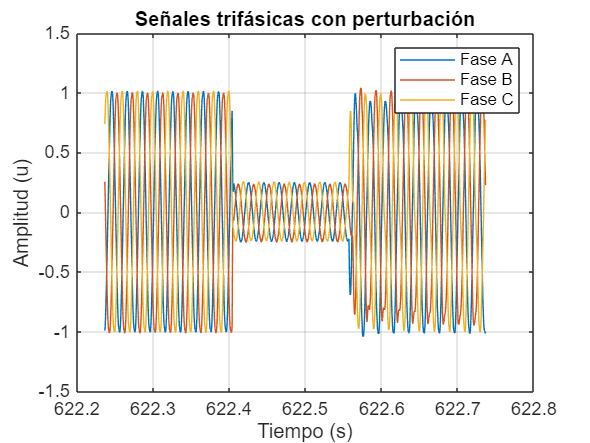


figure;
plot(t, v(1,:),t,v(2,:),t,v(3,:));
title('Señales trifásicas con perturbación');
xlabel('Tiempo (s)');
ylabel('Amplitud (u)');
legend('Fase A', 'Fase B', 'Fase C');
grid on;

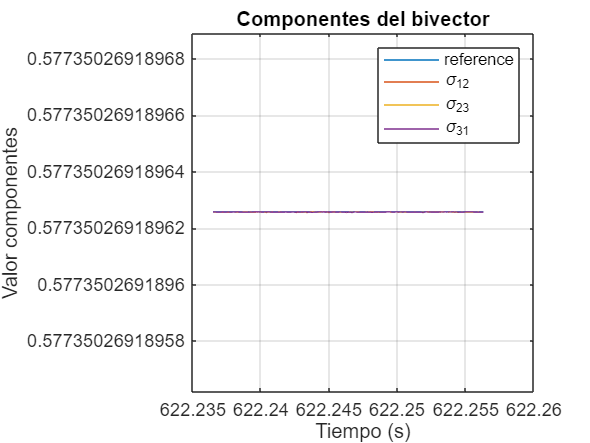


t2 = t(1:length(angle));

figure;
plot(t2,(1/sqrt(3))*ones(1,length(t2)),t2,bivector_normalized(1,:),t2,bivector_normalized(2,:),t2,bivector_normalized(3,:));
title('Componentes del bivector');
xlabel('Tiempo (s)');
ylabel('Valor componentes');
legend_labels2 = {"reference","\sigma_{12}","\sigma_{23}","\sigma_{31}"};
legend(legend_labels2);
grid on;

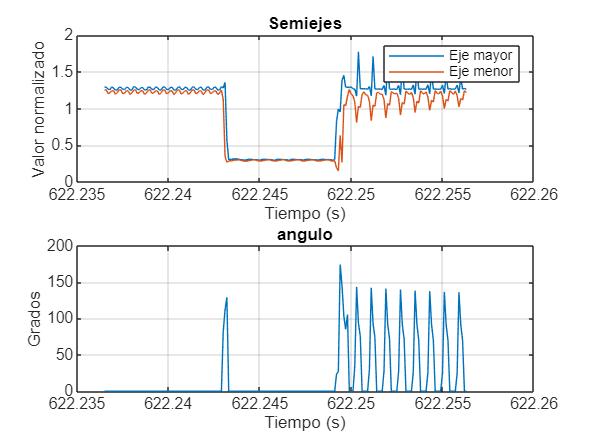


figure;
subplot(2,1,1)
plot(t2,semiaxes(1,:),t2,semiaxes(2,:));
title('Semiejes');
xlabel('Tiempo (s)');
ylabel('Valor normalizado');
legend_labels2 = {"Eje mayor","Eje menor"};
legend(legend_labels2);
grid on;

subplot(2,1,2)
plot(t2,angle*180/pi);
title('angulo');
xlabel('Tiempo (s)');
ylabel('Grados');
grid on;